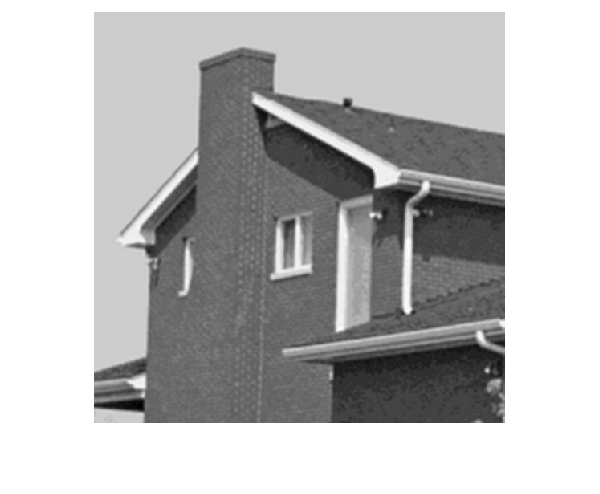

img = imread("../images/house.tif");
imshow(img)

[M, N] = size(img);
pad_img = padarray(img, [2, 2], "symmetric", "both");

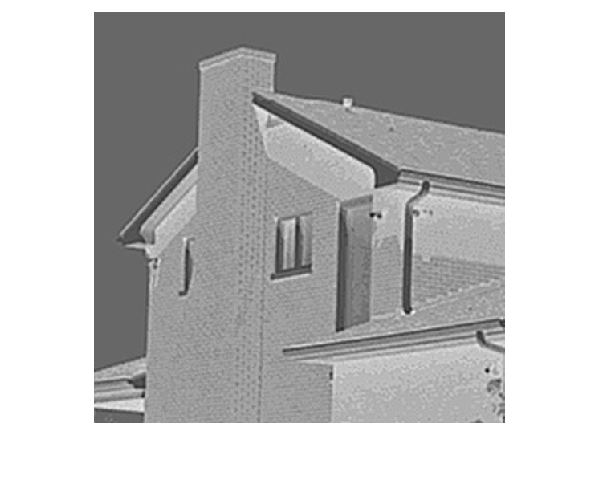

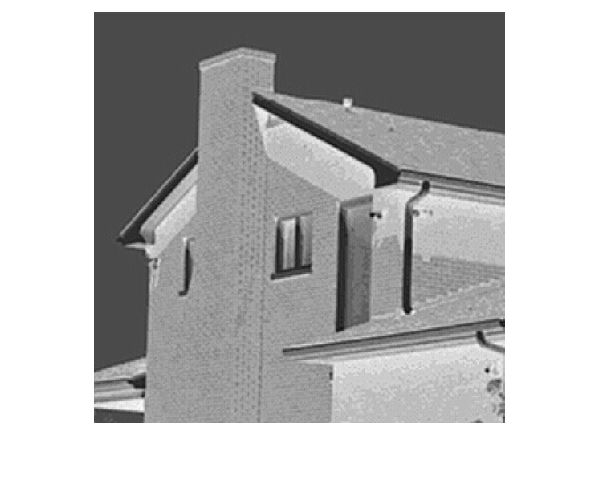

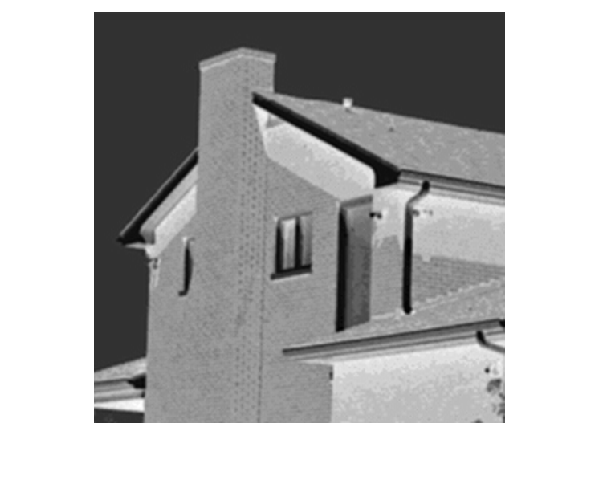

LoG_kernel = zeros(5, 5);
sigma = [1 0.5 0.25];
for k = 1:3
    s = sigma(k);
    for i = -2:2
        for j = -2:2
    %       computing elements in LoG kernel
            LoG_kernel(i+3, j+3) = -1/(pi*s^4) * (1 - (i^2 + j^2) / (2*s^2)) * exp(-(i^2 + j^2)/(2*s^2));
        end
    end
    LoG_res = zeros(M, N);
    % convolution between img and LoG kernel
    for i = 1:M
        for j = 1:N
            LoG_res(i, j) = sum(sum(double(pad_img(i:i+4, j:j+4)) .* LoG_kernel));
        end
    end
    % adjust intensity interval for visualization purposes
    LoG_res = LoG_res - min(min(LoG_res));
    LoG_res = LoG_res / max(max(LoG_res)) * 255;
    figure;
    imshow(uint8(LoG_res))
%     title('LoG filter with sigma='+int2str(s));
end

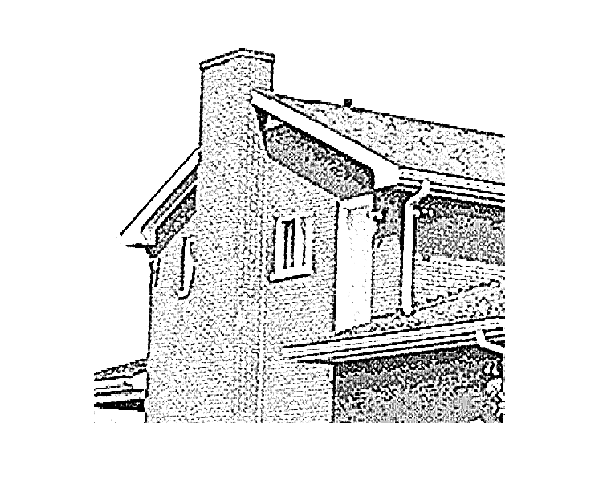

Gaussian_kernel = zeros(5, 5);
% smooth_kernel = [1/25 1/25 1/25 1/25 1/25;
%                  1/25 1/25 1/25 1/25 1/25;
%                  1/25 1/25 1/25 1/25 1/25;
%                  1/25 1/25 1/25 1/25 1/25;
%                  1/25 1/25 1/25 1/25 1/25];
for i = -2:2
    for j = -2:2
%       computing element in Gaussian kernel with sigma^2 = 1.
        Gaussian_kernel(i+3, j+3) = 1/(2 * pi) * exp(-(i^2 + j^2)/2);
    end
end
smooth_res = zeros(M, N);
% smooth img
for i = 1:M
    for j = 1:N
        smooth_res(i, j) = sum(sum(double(pad_img(i:i+4, j:j+4)) .* Gaussian_kernel));
    end
end
mask = double(img) - smooth_res;
% set k = 100
unsharpen_res = double(img) + 100 * mask;
imshow(uint8(unsharpen_res))